### Demo

clear % Add repository folders to path
mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
folder_path = strsplit(mfilePath,filesep);
repo_path = join([folder_path(1:end-2)],filesep);
repo_path = repo_path{1};
data_path = [repo_path,filesep,'data'];
src_path = [repo_path,filesep,'src'];
tenandet_path = [repo_path,filesep,'tenandet'];
testbench_path = [repo_path,filesep,'testbench'];
addpath(genpath(data_path), genpath(src_path),genpath(tenandet_path), genpath(testbench_path));
clear folder_path mfilePath repo_path data_path testbench_path src_path tenandet_path

### Load NYC data

sizes = [144,7,52,10]; % Load NYC data 
load nyc_tensors.mat
load regions.mat
arrs = squeeze(sum(reshape(arrs,6,24,365,[]),1)); 
Y = double(reshape(arrs(:,1:364,regions), 24, 7, 52,[]));   % Select 81 zones
Y(:,1,53,:) = arrs(:,365,regions);
Y(:,2:7,53,:) = mean(Y(:,2:7,1:52,:),3);                    % Fill in the last week with the mean of other weeks

###  Generate synthetic data with synthetic anomalies

**Parameters:**

- `number_anomaly`: Number of anomalous points

- `length_anomaly` : Anomaly length

- `amplitude_anomaly`: Amplitude of the anomaly

**Variables:**

- `Y_gen`: Simulated ground truth

- `Yn`: Simulated anomalous data

- `M`: Mask tensor. 1's indicate the anomalous entries

sizes = [24,7,53,81];   
number_anomaly = 1000;
length_anomaly = 8;
amplitude_anomaly = 4;
[M, Y_gen, Yn, ind_removed, mat_anom] =gendata(sizes, number_anomaly, length_anomaly, amplitude_anomaly, Y);
m= t2m(M,4); 
y= t2m(Y_gen,4);
z= t2m(Yn,4);

### Example plot:

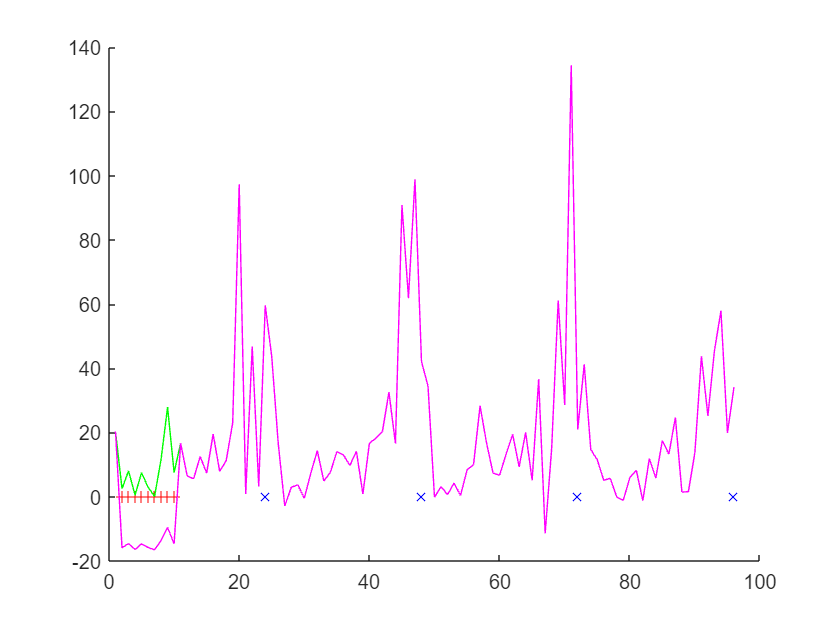

t= [1:200];
figure;
scatter(t(mod(1:96,24)==0),0,'bx')
hold on;

scatter(t(m(28,1:96)==1),0,'r+')
hold on
plot(y(28,1:96),'g')
plot(z(28,1:96),'m')

### Example implementation of LOSS Function:

Parameters follow Dr. Aviyente and Emres' GLOSS paper.

param = set_params(Yn);
param.beta_1=0.1;
param.beta_2=0.1;
param.beta_3=0.1;
% param.lambda=1/81;
% param.gamma=1/81;
% param.psi=1;
% param.alpha=0;
param.err_tol=1e-5;
param.max_iter=300;
param.ind_m =ind_removed;
[L,S,Nt,times]= loss(Yn, param);

Max iter


#### Example Algorithm Result:

- `S: Smooth and Sparse part (plotted in black)`

- `L: Low-rank part          (plotted in blue)`

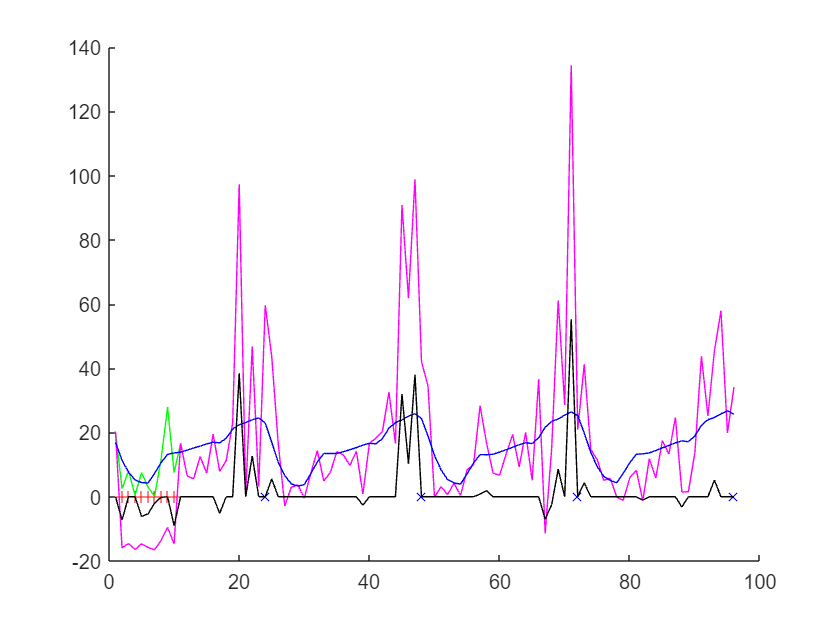

s= t2m(S,4);
l= t2m(L,4);
figure;
scatter(t(mod(1:96,24)==0),0,'bx')
hold on;

scatter(t(m(28,1:96)==1),0,'r+')
hold on
plot(y(28,1:96),'g')
plot(z(28,1:96),'m')
plot(l(28,1:96),'blue')
plot(s(28,1:96),'k')

norm(Yn-L-S,'fro')

ans = 1.6695e+04